%Sarasij Banerjee, Feb 20, 2024
%This script is an attempt to generate multisine input signals with
%time-domain constraints such as output constraints in the presence of a
%plant model
clear
clc
load mag_speed_3_ts_5_60_mins_freq.mat
load proc_model_day_9.mat

phi_init=(pi/5)*ones(length(p_spec),1);%[8;25;15;20;5]
omega_vec = p_spec(:,1);
sig_amp = 10;
amp_vec = sig_amp*p_spec(:,2)./norm(p_spec(:,2),2);
sig_len=60*60;
Ts = 5*60;
t_vec = 1:Ts:sig_len;

G_min= P1D(1);
G_c=chgTimeUnit(G_min,'seconds');
G_idtf=idtf(G_c);
G = c2d(G_idtf,Ts)

G =
 
  From input "u1" to output "y1":
            -0.0213 z^-1
  z^(-1) * ---------------
           1 - 0.6806 z^-1
 
Sample time: 300 seconds
Discrete-time identified transfer function.

Parameterization:
   Number of poles: 1   Number of zeros: 1
   Number of free coefficients: 2
   Use "tfdata", "getpvec", "getcov" for parameters and their uncertainties.

Status:                                                         
Created by direct construction or transformation. Not estimated.


fun = @(phi_vec)msine_func(phi_vec,omega_vec,amp_vec,t_vec,Ts,G)

fun = function_handle with value:
    @(phi_vec)msine_func(phi_vec,omega_vec,amp_vec,t_vec,Ts,G)


y_min = 7;
y_max =9;

lb=pi/2*ones(length(phi_init),1);
ub=pi*ones(length(phi_init),1);

nonlcon = @(phi_vec)out_constr(phi_vec,omega_vec,amp_vec,t_vec,Ts,y_min,y_max,G)

nonlcon = function_handle with value:
    @(phi_vec)out_constr(phi_vec,omega_vec,amp_vec,t_vec,Ts,y_min,y_max,G)


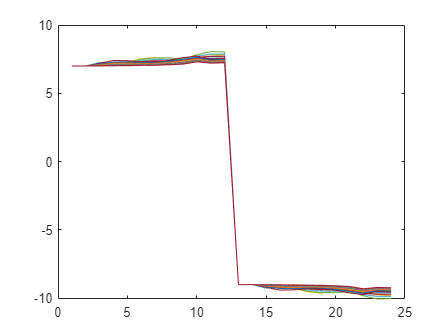


Converged to an infeasible point.

fmincon stopped because the size of the current step is less than
the value of the step size tolerance but constraints are not
satisfied to within the value of the constraint tolerance.

<stopping criteria details>



options = optimoptions(@fmincon,'Algorithm','sqp');

[phi_min,min_cf_sc]=fmincon(fun,phi_init,[],[],[],[],lb,ub,nonlcon,options);


min_cf = min_cf_sc*sqrt(2*length(p_spec))

min_cf = 1.5890

syms t
msine_final=sum (amp_vec.*sin(omega_vec*t+phi_min)); 

t=t_vec'

t =            1
         301
         601
         901
        1201
        1501
        1801
        2101
        2401
        2701


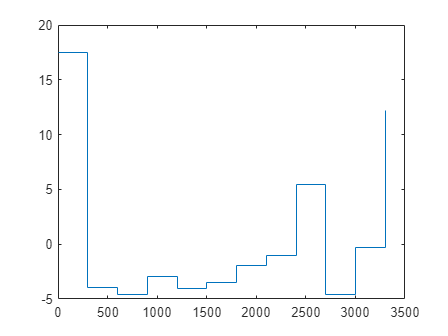

u_vec=double(subs(msine_final));
% u_vec = (u_vec - min(u_vec))./((max(u_vec)-min(u_vec)))
figure;stairs(t_vec,u_vec);

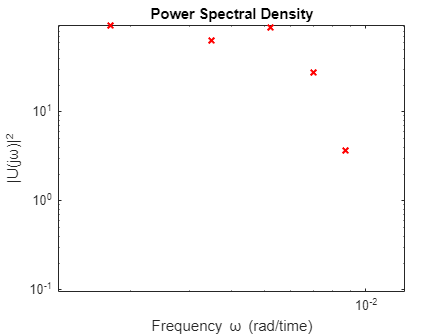

ans =     5.6641   94.5604   63.6547   89.5314   27.4442    3.6875   20.5461    3.6875   27.4442   89.5314   63.6547   94.5604


mypsd(u_vec,2*length(p_spec),Ts)

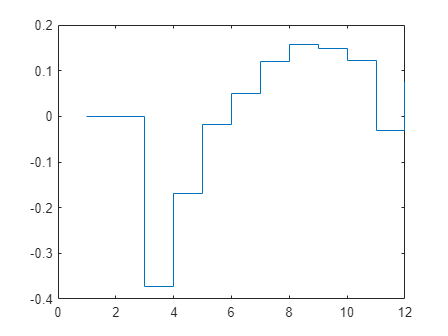


y_sim = lsim(G,u_vec,t_vec);
figure;stairs(y_sim)




% u_vec_sc=[zeros(5,1);u_vec-min(u_vec)];
% y=lsim(G,u_vec_sc, [1:Ts:length(u_vec_sc)*Ts]');
% figure;plot([1:Ts:length(u_vec_sc)*Ts]',y)
% % figure;scatter(u_vec,y)
% figure;subplot(2,1,1);stairs([1:Ts:length(u_vec_sc)*Ts]',y);subplot(2,1,2);stairs([1:Ts:length(u_vec_sc)*Ts]',u_vec_sc)
